# Homework 10

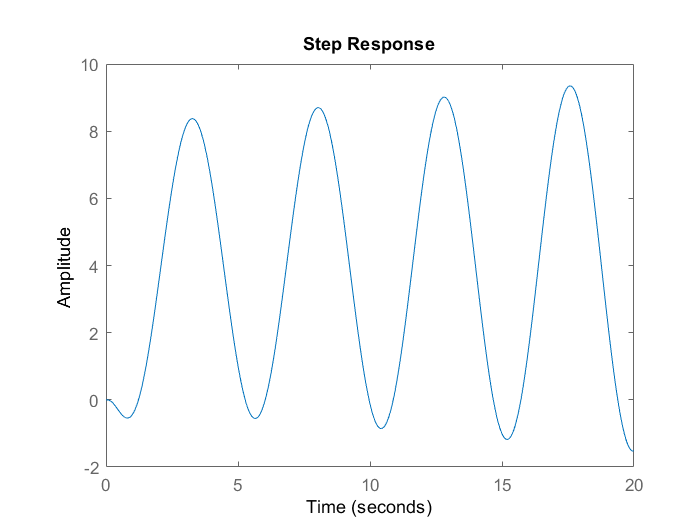

clear
clc

s = tf('s');

tau = 0.9;

pilot = (-(s+1) * (tau * s - 1.8))/((0.6 * s + 0.9) *((tau * s) +2));
servo = -10/(s+10);
aircraft = -(s+6) / (s*(s^2 + 3*s+ 6));

sys_tot = feedback(pilot * servo * aircraft, 1);

step(sys_tot * (4), 20)


%system is unstable at this reaction time

## part b

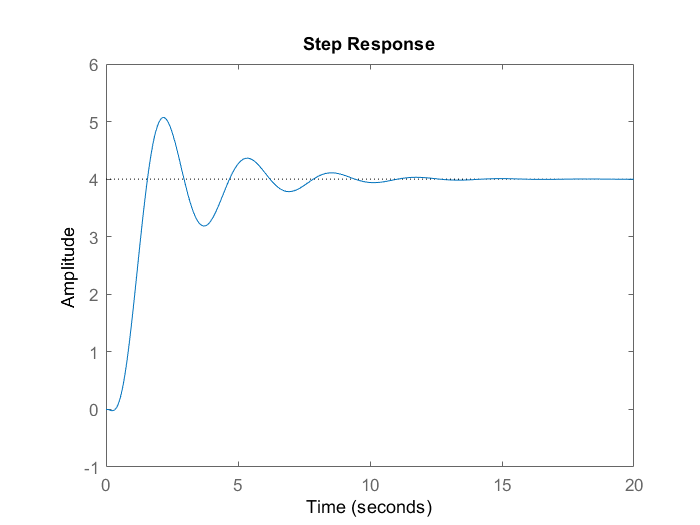

clear
clc

s = tf('s');

tau = 0.2;

pilot = (-(s+1) * (tau * s - 1.8))/((0.6 * s + 0.9) *((tau * s) +2));
servo = -10/(s+10);
aircraft = -(s+6) / (s*(s^2 + 3*s+ 6));

sys_tot = feedback(pilot * servo * aircraft, 1);

step(sys_tot * (4), 20)


%system becomes stable very quickly at this
%reaction time

## part c

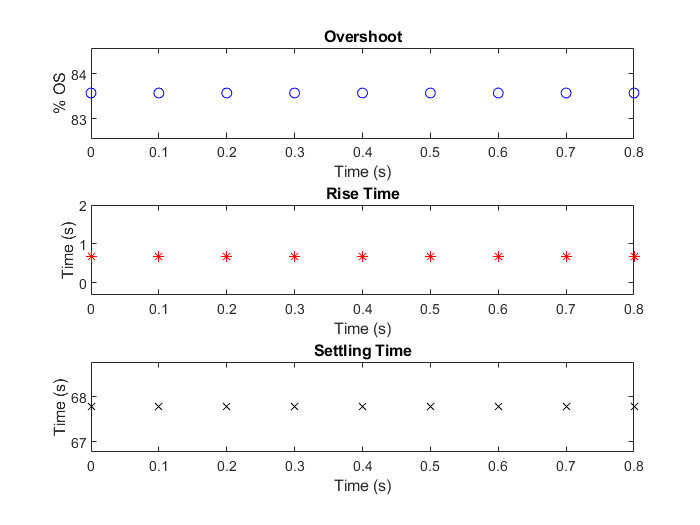

clear
clc

s = tf('s');
i = 1;
for tau = 0:0.1:1
    
    pilot = (-(s+1) * (tau * s - 1.8))/((0.6 * s + 0.9) *((tau * s) +2));
    servo = -10/(s+10);
    aircraft = -(s+6) / (s*(s^2 + 3*s+ 6));

    sys_tot = feedback(pilot * servo * aircraft, 1);

    S(i) = stepinfo(sys_tot);
    
    i = i+1;
end

time = 0:0.1:0.8;

for n = 1:1:8
    
    subplot(3,1,1)
    plot(time,S(n).Overshoot, 'bo')
    title('Overshoot')
    xlabel('Time (s)')
    ylabel('% OS')
    
    subplot(3,1,2)
    plot(time,S(n).RiseTime, 'r*')
    title('Rise Time')
    xlabel('Time (s)')
    ylabel('Time (s)')
    
    subplot(3,1,3)
    plot(time,S(n).SettlingTime, 'kx')
    title('Settling Time')
    xlabel('Time (s)')
    ylabel('Time (s)')
    
end

## d

clear
clc
s = tf('s');

i = 1;
for tau = 0:0.05:1
    
    pilot = (-(s+1) * (tau * s - 1.8))/((0.6 * s + 0.9) *((tau * s) +2));
    servo = -10/(s+10);
    aircraft = -(s+6) / (s*(s^2 + 3*s+ 6));

    sys_tot = feedback(pilot * servo * aircraft, 1);

    S(i) = stepinfo(sys_tot);
    
    i = i+1;
end

time_min = S(16).SettlingTime / 60

time_min = 1.7146

time_min = S(17).SettlingTime / 60

time_min = 3.3490

time_min = S(18).SettlingTime / 60

time_min = 29.6673

% at 0.9 s reaction time the settling time becomes 
% 1780 s which is about 30 min. probably too slow 
%for a fighter pilot

%if only seeking for closed loop stability, 
% tau of 0.9 maximum

## e

%average human reaction time is about .25s
%this is well within the range to maintain
%stability of the aircraft.
%additionally, one can safely assume these
%are not "average" humans